# **TU: SVM classification**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

Author: Jin Kwak/21900031

Date  : 24.09.20

## Introduction

Classification with SVM

## Example: Circular Distribution

### Dataset 1:  Random Generation for Circular Distribution

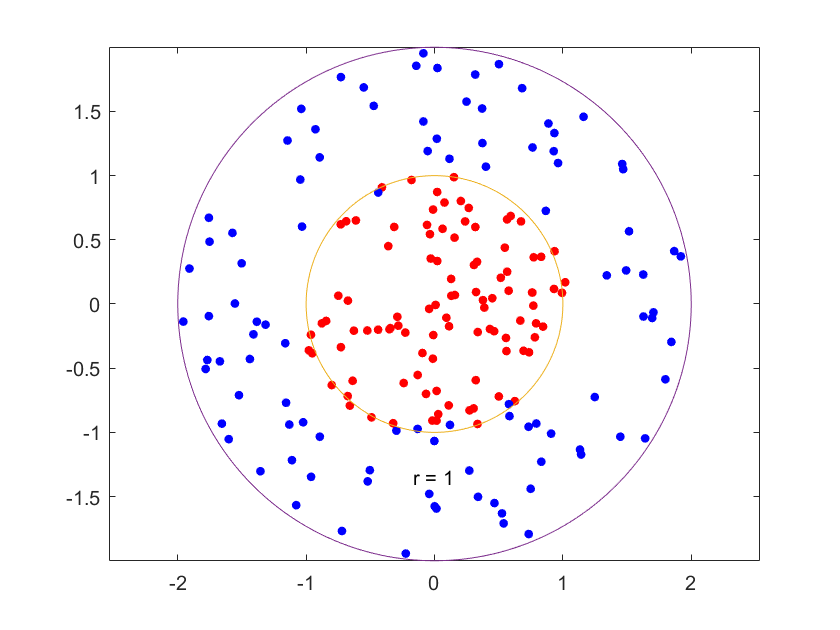

rng(1); % For reproducibility

% Class y=-1
r = sqrt(1.1*rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points
% Class y=1
r2 = sqrt(3*rand(100,1)+0.9); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points

dataC = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;

figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
ezpolar(@(x)1);ezpolar(@(x)2);
axis equal
hold off

### Train SVM 

% With Box Constraint =inf
cl = fitcsvm(dataC,theclass,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);

% With Box Constraint default - Also check the result
cl = fitcsvm(dataC,theclass,'KernelFunction','rbf','BoxConstraint',1,'ClassNames',[-1,1]);


### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

mlResubErr = resubLoss(cl)

mlResubErr = 0.0350

**Confusion matrix** on the training set

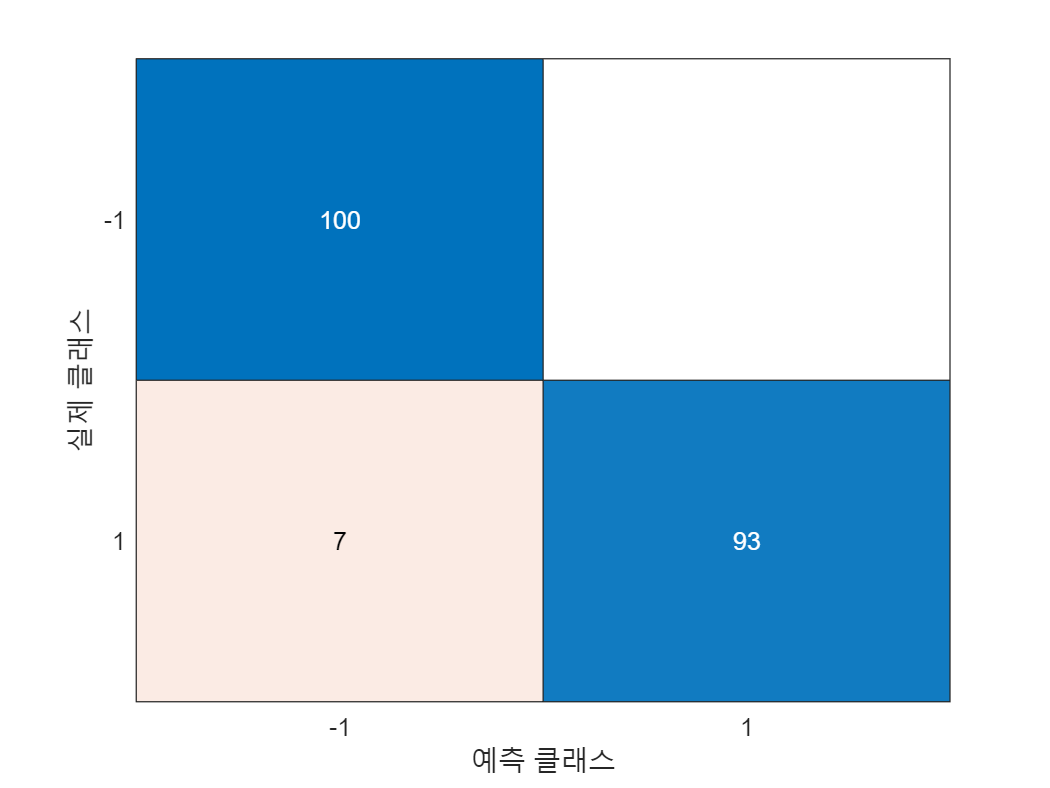

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(theclass,mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(dataC(:,1)):d:max(dataC(:,1)),...
    min(dataC(:,2)):d:max(dataC(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);


**Plot the data and the decision boundary**

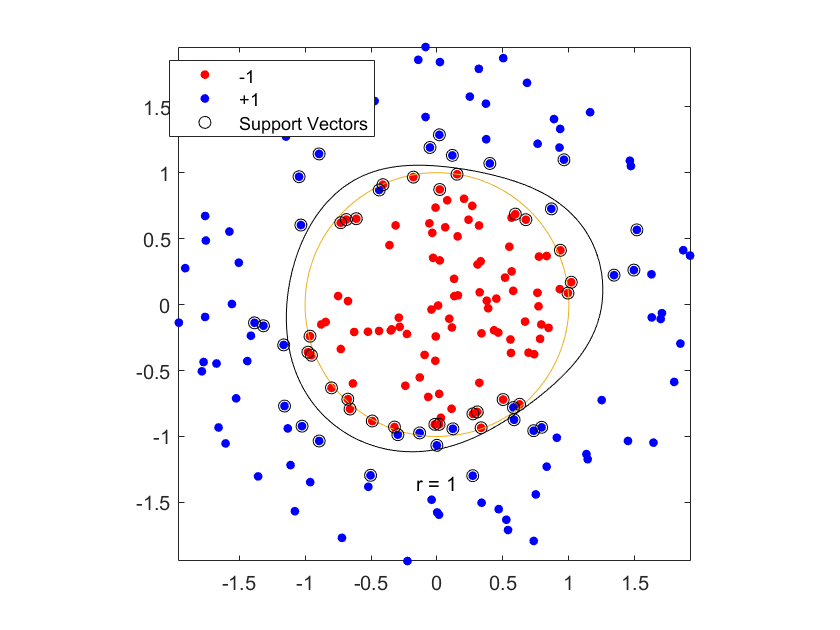

figure;
h(1:2) = gscatter(dataC(:,1),dataC(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(dataC(cl.IsSupportVector,1),dataC(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

rng(0)
cp = cvpartition(theclass,'KFold',10)  %k-fold

cp = K-겹 교차 검증 분할
   NumObservations: 200
       NumTestSets: 10
         TrainSize: 180  180  180  180  180  180  180  180  180  180
          TestSize: 20  20  20  20  20  20  20  20  20  20

cvml = crossval(cl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0450

# Exercise  

## Exercise 1: SVM Classification with CWRU (binary class)

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- For binary class:  Outer and Inner Race Fault

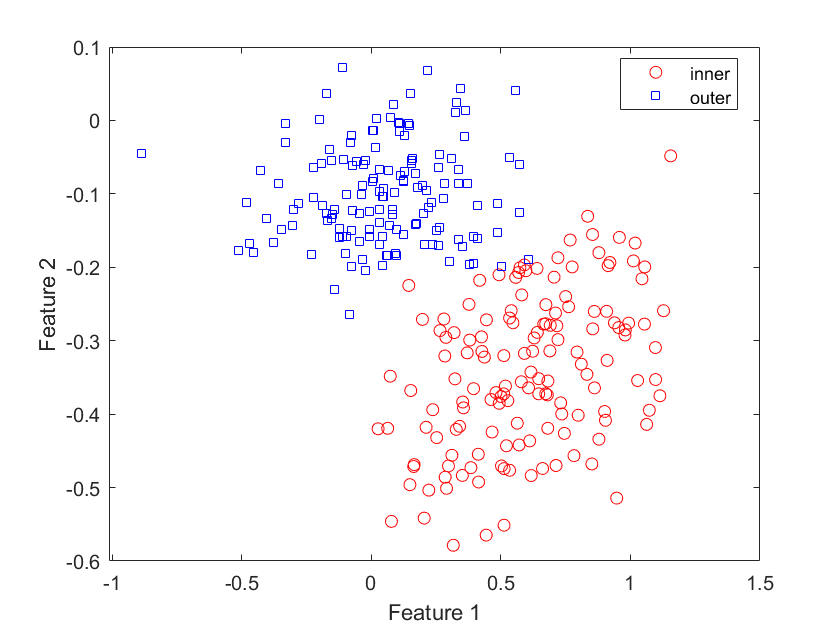

clear

% Eliminate clas 'normal'. Keep 'Inner', 'Outer'
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");

feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));

Ytrain = class_cwru_train;       % fault class
classKeep = ~strcmp(Ytrain,'normal');
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);
N = size(X,1);

% Plot
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

### **CV Partition**

% cvpartition to generate k=10 disjoint stratified subsets.
k = 10;
the_class = ones(N,1);
the_class(1:floor(N/2)) = -1.0;
cv = cvpartition(the_class,'KFold',k);

###  Train SVM 

%%% YOUR CODE GOES HERE
% specifiy class name:  fitcsvm(..., 'ClassNames',{'outer','inner'})
s = Ytrain(classKeep);
cl = fitcsvm(X,Y,'KernelFunction','linear', ...
            'ClassNames',{'inner', 'outer'});

### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

%%% YOUR CODE GOES HERE
resubLoss(cl)

ans = 0.0313

**Confusion matrix** on the training set

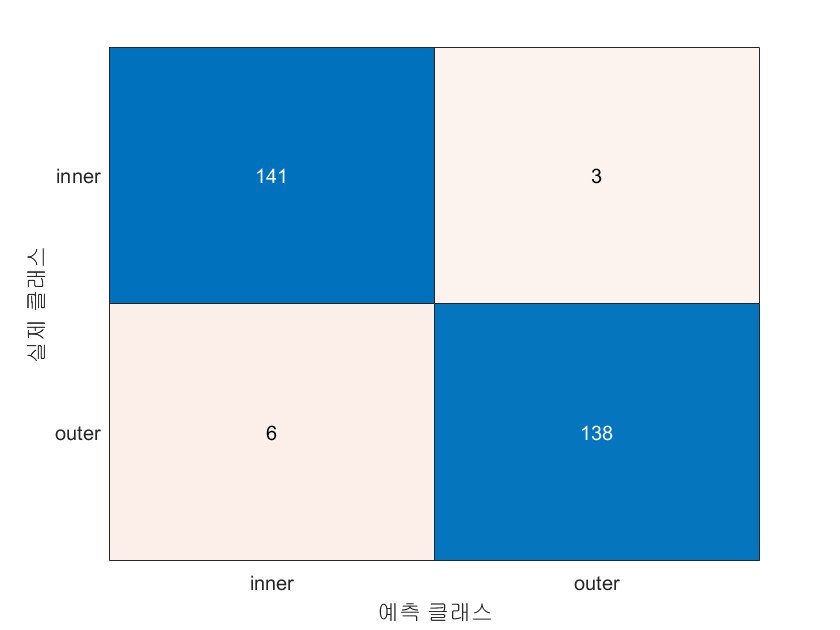

%%% YOUR CODE GOES HERE
mlClass = resubPredict(cl);

figure;
ldaResubCM = confusionchart(Y,mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];

[~,scores] = predict(cl,xGrid);

**Plot the data and the decision boundary**

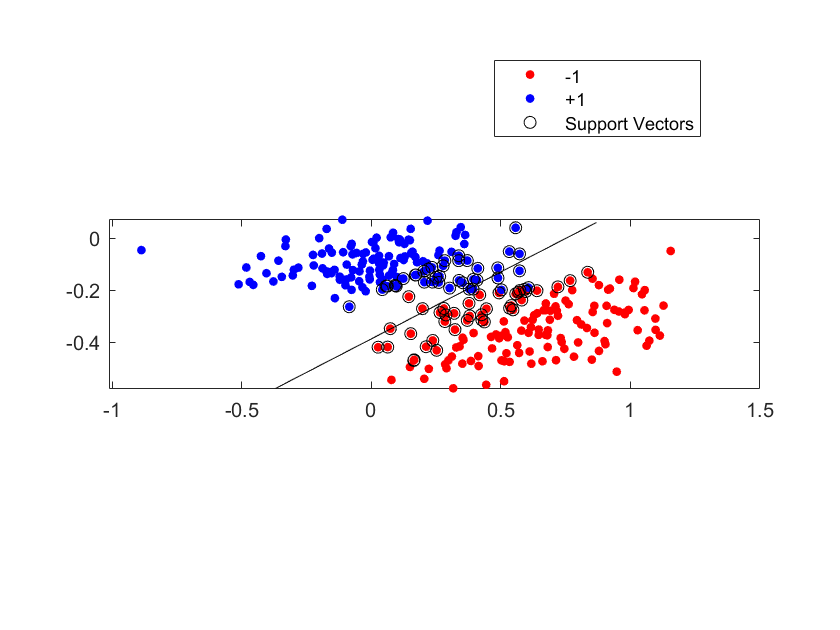

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y,'rb','.');
hold on
h(3) = plot(X(cl.IsSupportVector,1),X(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

%%% YOUR CODE GOES HERE
cv = cvpartition(Y,'KFold',10);


Cross validate and show cv loss

%%% YOUR CODE GOES HERE
cross_val= crossval(cl,'CVPartition',cv);
accuracy = 1- kfoldLoss(crossval(cl))

accuracy = 0.9688

mlCVError = kfoldLoss(cross_val)

mlCVError = 0.0313

## Exercise 2: SVM Classification with CWRU (3 classes)

Now, Use all 3 classes:  normal,  outer, inner.  Apply Multi_Class SVM 

**Features**

% Example
Xt(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
Xt(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
Xt(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

Analyze  the test and train results 

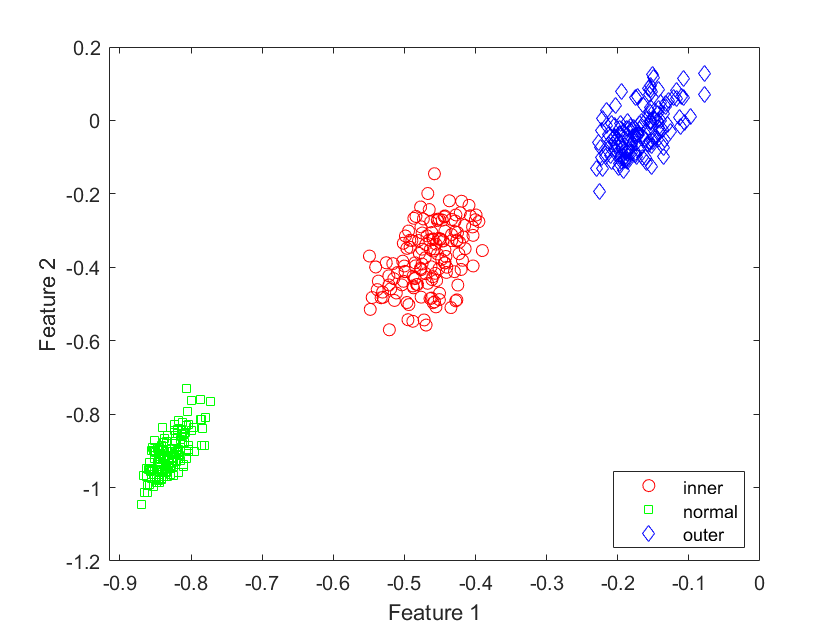

Y = class_cwru_train;
N = size(Xt,1);
Y = categorical(Y);
fig1 = figure;
gscatter(Xt(:,1), Xt(:,2), Y,'rgb','osd');
xlabel('Feature 1');
ylabel('Feature 2');

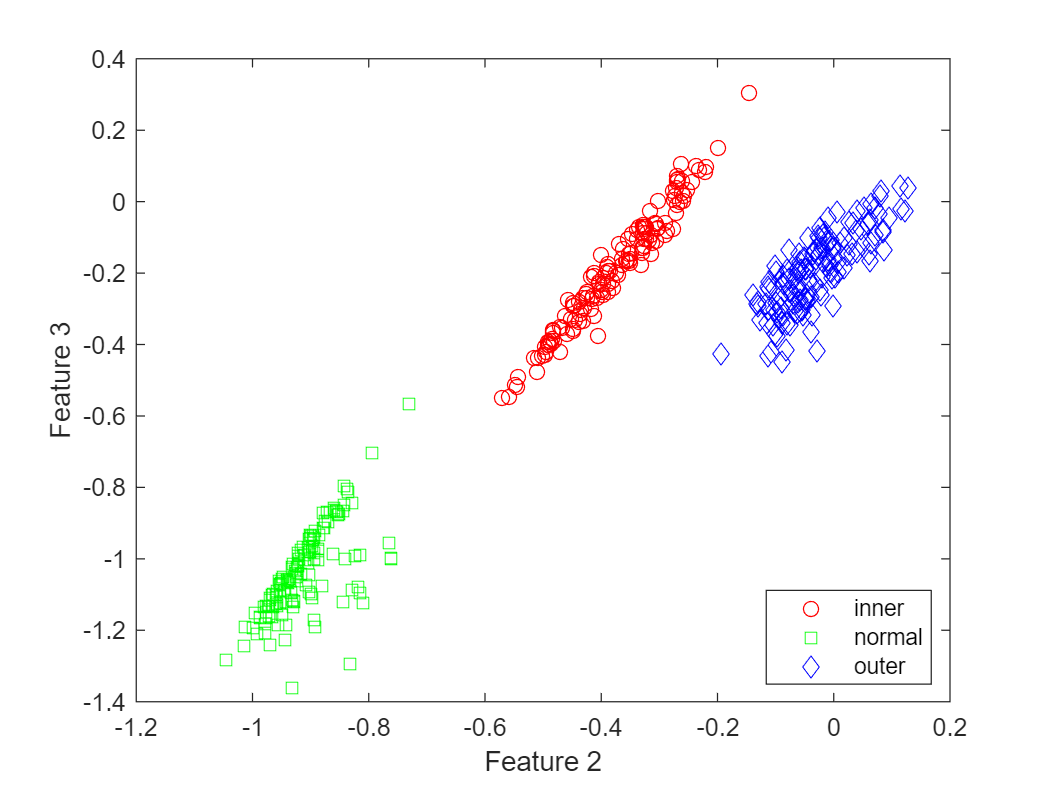

gscatter(Xt(:,2), Xt(:,3), Y,'rgb','osd');
xlabel('Feature 2');
ylabel('Feature 3');

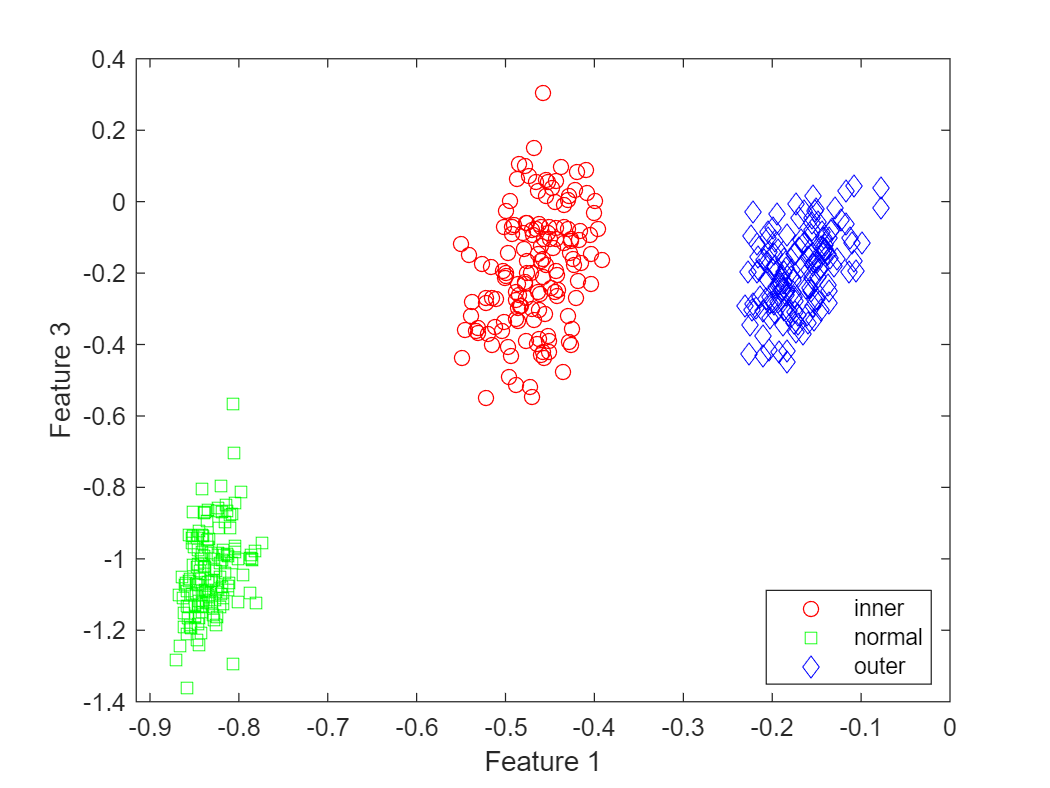

gscatter(Xt(:,1), Xt(:,3), Y,'rgb','osd');
xlabel('Feature 1');
ylabel('Feature 3');

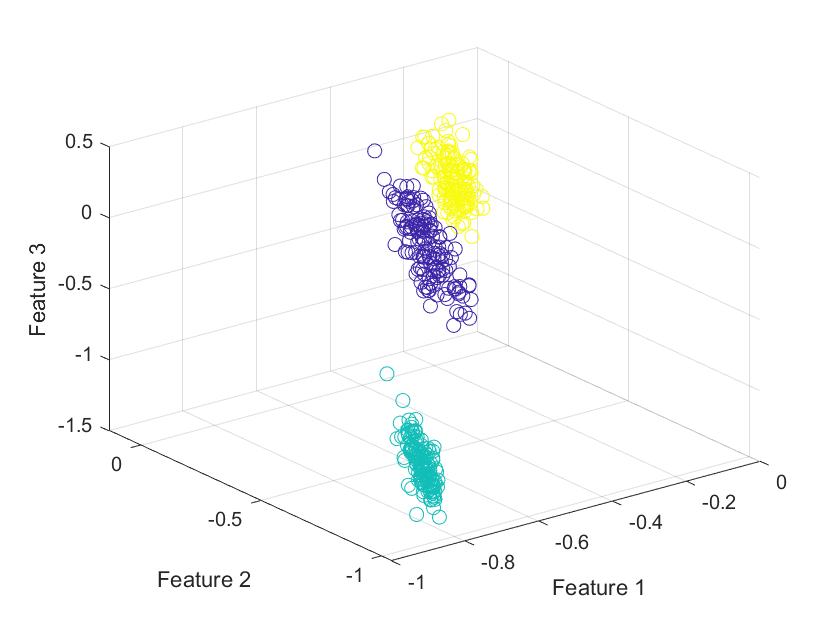

fig = figure;
scatter3(Xt(:,1), Xt(:,2), Xt(:,3), 50, Y);
xlabel('Feature 1');
ylabel('Feature 2');
zlabel('Feature 3');
grid on;

cv = cvpartition(Y, 'KFold', 10);
cl = fitcecoc(Xt, Y, 'Learners', 'svm','FitPosterior',true, ...
 'ClassNames', {'outer', 'inner', 'normal'}, ...
 'Verbose',2);

144개의 음성 관측값과 144개의 양성 관측값을 사용하여 전체 3개 중에서 이진 학습기 1(SVM)을(를) 훈련시키는 중입니다.
음성 클래스 인덱스: 2
양성 클래스 인덱스: 1

학습기 1(SVM)에 대해 사후 확률을 피팅하는 중입니다.
144개의 음성 관측값과 144개의 양성 관측값을 사용하여 전체 3개 중에서 이진 학습기 2(SVM)을(를) 훈련시키는 중입니다.
음성 클래스 인덱스: 3
양성 클래스 인덱스: 1

학습기 2(SVM)에 대해 사후 확률을 피팅하는 중입니다.
144개의 음성 관측값과 144개의 양성 관측값을 사용하여 전체 3개 중에서 이진 학습기 3(SVM)을(를) 훈련시키는 중입니다.
음성 클래스 인덱스: 3
양성 클래스 인덱스: 2

학습기 3(SVM)에 대해 사후 확률을 피팅하는 중입니다.


resubLoss(cl)

ans = 0

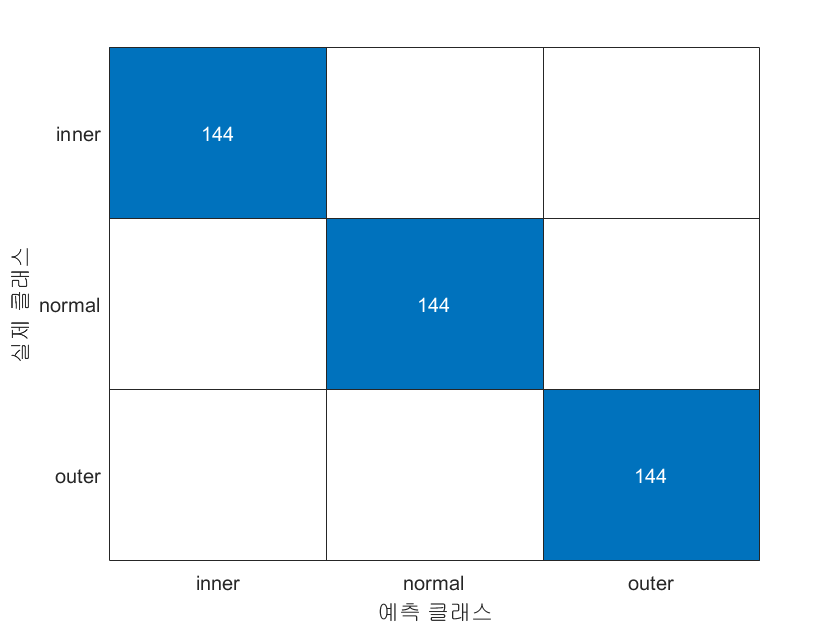

mlClass = resubPredict(cl);
mlClass = categorical(mlClass);
figure; 
conf_mat = confusionchart(Y,mlClass);

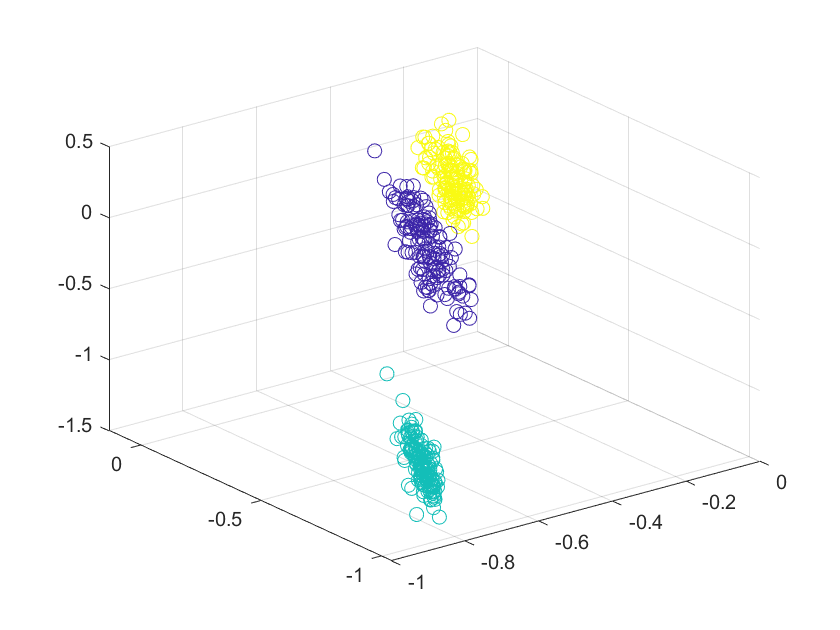

d = 0.02;
[x1Grid,x2Grid,x3Grid] = meshgrid(min(Xt(:,1)):d:max(Xt(:,1)),...
                                  min(Xt(:,2)):d:max(Xt(:,2)), ...
                                  min(Xt(:,3)):d:max(Xt(:,3)));
xGrid = [x1Grid(:),x2Grid(:),x3Grid(:)];
[~,scores] = predict(cl,xGrid);
figure;
scatter3(Xt(:,1), Xt(:,2), Xt(:,3), 50, Y);

Compare performance of SVM with  other models such as Logistic Regression

SVM has the advantage of interpretation as the dimensionality increases.

SVM has high speed of prediction

Compared to Logistic Regression, it can classify multiple classes while logistic regression is suitable for 2 class(true/false).

Reference

- [https://bluehyena.tistory.com/entry/Classification-Methods-%EB%B6%84%EB%A5%98-%EB%B0%A9%EB%B2%95-%EC%9A%94%EC%95%BD-%EB%B0%8F-%EB%9D%BC%EC%9D%B4%EB%B8%8C%EB%9F%AC%EB%A6%AC-%EC%A0%95%EB%A6%AC](https://bluehyena.tistory.com/entry/Classification-Methods-%EB%B6%84%EB%A5%98-%EB%B0%A9%EB%B2%95-%EC%9A%94%EC%95%BD-%EB%B0%8F-%EB%9D%BC%EC%9D%B4%EB%B8%8C%EB%9F%AC%EB%A6%AC-%EC%A0%95%EB%A6%AC) 

- [https://dad-rock.tistory.com/714](https://dad-rock.tistory.com/714) 